# DSP Take-Home Test

Samuel Stark (sws35)

November 2021

## Question 1

Consider the following discrete systems (not pictured):

List which of these are 

**a) Linear**

B, E, F, G are linear.

A includes absolute-value => non linear.

C:$\begin{array}{l}
T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace =\frac{3\left({\textrm{az}}_{n-1} +{\textrm{bu}}_{n-1} \right)+\left({\textrm{az}}_{n-2} +{\textrm{bu}}_{n-2} \right)}{{\textrm{az}}_{n-3} +{\textrm{bu}}_{n-3} }\\
\textrm{aT}\left\lbrace z_n \right\rbrace +\textrm{bT}\left\lbrace u_n \right\rbrace =a\left(\frac{3z_{n-1} +z_{n-2} }{z_{n-3} }\right)+b\left(\frac{3u_{n-1} +u_{n-2} }{u_{n-3} }\right)\not= T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace 
\end{array}$

D:$\begin{array}{l}
\;T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace =\prod_{i=0}^8 \left({\textrm{az}}_{n-i} +{\textrm{bu}}_{n-i} \right)\\
\textrm{aT}\left\lbrace z_n \right\rbrace +\textrm{bT}\left\lbrace u_n \right\rbrace =a\prod_{i=0}^8 z_{n-i} +b\prod_{i=0}^8 u_{n-i} \not= T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace 
\end{array}$

H: $\begin{array}{l}
\;T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace =\left({\textrm{az}}_n +{\textrm{bu}}_n \right)+\cos \left(0\ldotp 7\pi n\right)\\
\textrm{aT}\left\lbrace z_n \right\rbrace +\textrm{bT}\left\lbrace u_n \right\rbrace ={\textrm{az}}_n +{\textrm{bu}}_n +2\cos \left(0\ldotp 7\pi n\right)\not= T\left\lbrace {\textrm{az}}_n +{\textrm{bu}}_n \right\rbrace 
\end{array}$

**b) Time-Invariant**

A, C, D are time invariant.

B: $\begin{array}{l}
y_{n-d} =0\ldotp 5\left(x_{2n-d} +x_{2n+1-d} \right)\\
T\left\lbrace x_{n-d} \right\rbrace =0\ldotp 5\left(x_{2\left(n-d\right)} +x_{2\left(n-d\right)+1} \right)=0\ldotp 5\left(x_{2n-2d} +x_{2n-2d+1} \right)\not= y_{n-d} 
\end{array}$

E: $\begin{array}{l}
y_{n-d} =\sum_{i=-\infty }^{\infty } x_i *\delta_{i-n+d+2} \\
T\left\lbrace x_{n-d} \right\rbrace =\sum_{i=-\infty }^{\infty } x_{i-d} *\delta_{i-n+2} =y_n \not= y_{n-d} 
\end{array}$

F: $\begin{array}{l}
y_{n-d} =x_{n-d} e^{\frac{\left(n-d\right)}{14}} \\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} e^{\frac{n}{14}} \not= y_{n-d} 
\end{array}$

G: $\begin{array}{l}
y_{n-d} =x_{n-d} u_{n-d} \\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} u_n \not= y_{n-d} 
\end{array}$

H:$\begin{array}{l}
y_{n-d} =x_{n-d} +\cos \left(0\ldotp 7\pi \left(n-d\right)\right)\\
T\left\lbrace x_{n-d} \right\rbrace =x_{n-d} +\cos \left(0\ldotp 7\pi n\right)\not= y_{n-d} 
\end{array}$

**c) Causal**

C, D, F, G, H are causal.

A, B, E include references to $x_k \;\textrm{for}\;k>n$ => non-causal

**d) Memoryless**

F, G, H are memoryless.

A, B, C, D, E include references to $x_k \;\textrm{for}\;k\not= n$ => use memory

## Question 2

A finite-support sequence is non-zero only at a finite number of positions. If m and n are the first and last non-zero positions, respectively, then we call $n-m+1$ the length of that sequence. What maximum length can the result of convolving two sequences of length k and l have?

The maximum length of the convolution = the distance between the farthest two ends of both sequences when they overlap by exactly one element = $k+l-1$

Example:

k = 6;
l = 9;
ks = [ones(1,k) zeros(1,l-1)];
ls = [zeros(1,k-1) ones(1,l)];
len = k + l - 1

len = 14

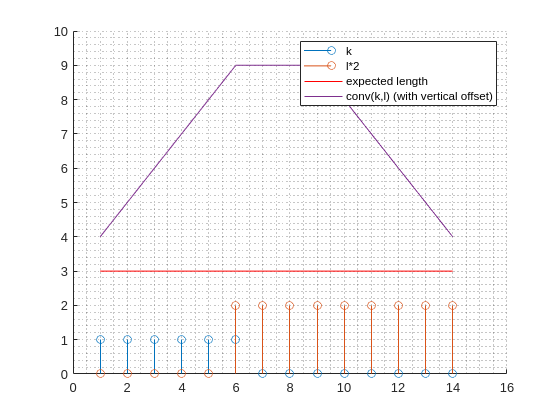


figure; 
hold on; 
stem(ks); stem(ls*2);
plot([1 len],[3 3],'r');
plot(3+conv(ones(1,k),ones(1,l)));
hold off;
legend("k","l*2","expected length","conv(k,l) (with vertical offset)")
ylim([0,10]); xlim([0,len+2]); grid minor;

## Question 3

**a) Find a pair of sequences **$\left\lbrace a_n \right\rbrace$** and **$\left\lbrace b_n \right\rbrace$**, where each one contains at least three different values and where the convolution **$\left\lbrace a_n \right\rbrace \ast \left\lbrace b_n \right\rbrace$** results in the all-zero sequence ...,0,0,0,....**

Convolution of a,b = $c_n =\sum_{k=-\infty }^{\infty } a_k \cdot b_{n-k}$

Note: one of a, b must be infinite. PROOF

assume a,b are both finite and nonzero. without loss of generality, assume $a_n ,b_n =0\;\forall \;n<0\;\;\;\textrm{and}\;\;\;a_0 ,b_0 \not= 0$. (e.g. that a,b both "start" at n=0.)


$$c_0 =$$

$$\sum_{k=-\infty }^{\infty } a_k \cdot b_{-k} =a_0 b_0 +a_1 b_{-1} +a_2 b_{-2} \ldotp \ldotp \ldotp =a_0 b_0 \;\;\left(\textrm{as}\;b_{-n} =0\right)$$



$$a_0 ,b_0 \not= 0\Rightarrow c_0 \not= 0$$


For finite nonzero a,b the convolution c will always have a nonzero tail.

Question 6's filter is equivalent to a convolution with the finite sequence [...0 1 -1 1 -1 0...] (which contains 3 different values {0,1,-1})

Question 6's filter eliminates frequencies of $\frac{f_s }{4}$ = an infinite sequence of [1 0 -1 0 1 0 -1 0]... (again, contains 3 different values {0,1,-1})

$a_n =\left(n\;\mathrm{mod}\;2\right)*{\left(-1\right)}^{\mathrm{floor}\left(\frac{n}{2}\right)} =$[0 1 0 -1 0 1 0 -1]...

$b_n =$[0 1 -1 1 -1 0]


$$\left\lbrace c_n \right\rbrace =\left\lbrace a_n \right\rbrace *\left\lbrace b_n \right\rbrace ,c_n =0\;\forall \;n$$


**b) Let T be an LTI system with an impulse response that is not the all-zero sequence. Does every such T have a corresponding inverse LTI system **$T^{-1}$** such that **$\left\lbrace x_n \right\rbrace =T^{-1} T\left\lbrace x_n \right\rbrace$** for all sequences **$\left\lbrace x_n \right\rbrace$**? Why or why not?**

No.

See Question 6 for an LTI system with nonzero impulse response that can completely eliminate a specific frequency (in this case, for sampling frequency 8kHz, it can eliminate 2kHz).

For this system, all inputs consisting of a 2kHz signal at any phase and nonzero amplitude will produce a zero result.

There cannot be an LTI system that can distinguish between these all-zero results to reproduce the specific original signals

=> this LTI system is uninvertible

=> not all LTI systems with nonzero impulse response are invertible.

## Question 4

**a) Which of 16kHz, 32kHz, 48kHz would be suitable for distinguishing two whistle tones of 23kHz, 25kHz?**

Only 32kHz could distinguish these.

Given a sample frequency $f_s$, you can reconstruct a signal with frequencies between $\frac{n*f_s }{2}<|f|<\frac{\left(n+1\right)*f_s }{2}$ for a specific $n$.

To distinguish the signals, this range must include 23kHz and 25kHz:

$f_S =16\textrm{kHz}:0-8;\;8-16;\;16-24;\;24-32\ldotp \ldotp \ldotp$ (no range with 23 and 25)

$f_S =48\textrm{kHz}:0-24;\;24-48\ldotp \ldotp \ldotp$ (no range with 23 and 25)

$f_S =32\textrm{kHz}:0-16;\;16-32$ (has a range with 23 and 25 for $n=1$)

**b) For each of the two whistles: for which k will **$|X_k |$**show a peak?**

Each whistle emits a sine tone => when one whistle blows, $x=\sin \left(2\pi \textrm{ft}\right)$

When sampling, $x_i =\sin \left(\frac{2\pi \textrm{fi}}{f_s }\right)=\sin \left(2\pi f*\frac{i}{n}*\frac{n}{f_s }\right)$

FFT peaks when this aligns with $e^{-2\pi j\;\frac{\textrm{ik}}{n}}$=>


$$\begin{array}{l}
2\pi \frac{i}{n}k=2\pi f*\frac{i}{n}*\frac{n}{f_s }\\
k=\frac{f*n}{f_s }
\end{array}$$


($\left.f_s =160\textrm{kHz}\right)$

Therefore for $f=23\textrm{kHz},k=\frac{23*512}{160}=73\ldotp 6\;\left(\textrm{rounds}\;\textrm{to}\;74\right)$. (this doesn't align with an FFT bucket perfectly => will scallop)

For $f=25\textrm{kHz},k=\frac{25*512}{160}=80$.

**c) Which tones will cause a higher peak in the FFT result, and why?**

As mentioned, the 23kHz signal does not align with an FFT bucket. This means it will not peak sharply on one bucket, but will scallop - the peak will spread to the buckets around the middle.

25kHz does align with an FFT bucket, so that peak will be higher than the scalloped 23kHz.

Proof:

f_s = 160E3;
f1 = 23E3;
f2 = 25E3;
block_size = 512;
blocks_per_s = f_s / block_size;
t_per_block = block_size / f_s;

t = (1/f_s):(1/f_s):t_per_block;
sampled_signal = sin(2*pi*f1*t) + sin(2*pi*f2*t);

% Adapted from https://uk.mathworks.com/help/matlab/ref/fft.html
% Compute the two-sided spectrum P2, with a hamming window.
% Then compute the single-sided spectrum P1 based on P2 and 
% the even-valued signal length L.
Y=fft(sampled_signal .* hamming(block_size)');
L=block_size;
P2 = abs(Y/L); % Normalize impact of FFT length
% P2 is two-sided eg. includes negative frequencies
% but P2 is also symmetric
% => one-sided version is 2*(first half of P2)
P1 = P2(1:L/2);
P1(2:end) = 2*P1(2:end);

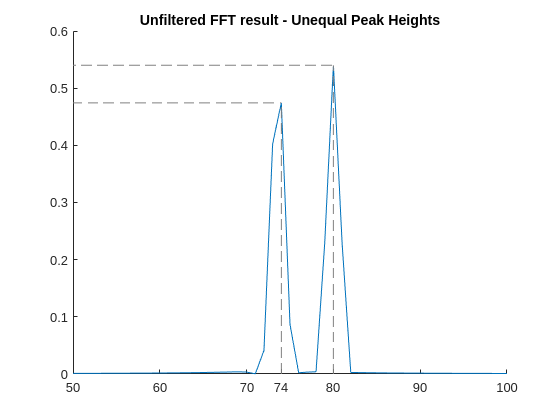

figure;
hold on;
plot(0:1:(L/2-1), P1);
% Plot lines at expected peaks
% MATLAB vectors are one-indexed, so the indices are 75 and 81
% y axis
plot([0,74],[P1(75),P1(75)],'--',"color",[0,0,0]+0.5);
plot([0,80],[P1(81),P1(81)],'--',"color",[0,0,0]+0.5);
% x axis
plot([74,74],[0,P1(75)],'--',"color",[0,0,0]+0.5);
plot([80,80],[0,P1(81)],'--',"color",[0,0,0]+0.5);
% Limit to interesting part of graph
xlim([50 100]);
xticks([50 60 70 74 80 90 100]);
title("Unfiltered FFT result - Unequal Peak Heights");
hold off;

**d) What additional linear processing step can you apply, and where, to reduce the relative amplitude difference between 23kHz and 25kHz?**

Apply a linear "4-point moving average" filter to the FFT result.

The scalloping distributes the peak among the adjacent buckets, and the moving average serves to pull them back together.

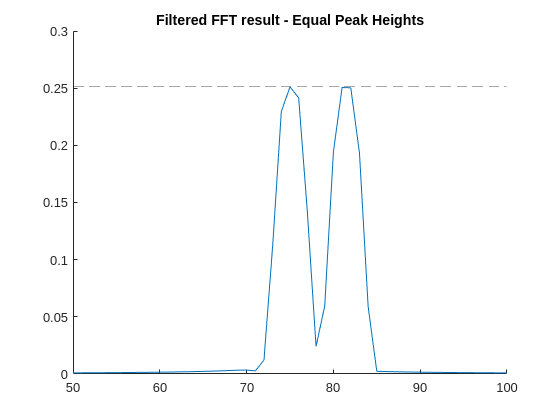

b=[1 1 1 1]/4;
a=[1];
P1_smoothed = filter(b, a, P1);

figure;
hold on;
plot(0:1:(L/2-1), P1_smoothed);
% The peaks won't be at exactly 74 or 80 now, though
yline(max(P1_smoothed),'--',"","color",[0,0,0]+0.5);
% Limit to interesting part of graph
xlim([50 100]);
title("Filtered FFT result - Equal Peak Heights");
hold off;

**e) Give an example of a second-order peak filter, operating at **$f_s$**=160kHz with pass frequency f=25kHz, in terms of the position of poles and zeros in the z-transform of its impulse response, providing an expression for H(z)**

First, I designed one with MATLAB Filter Designer:

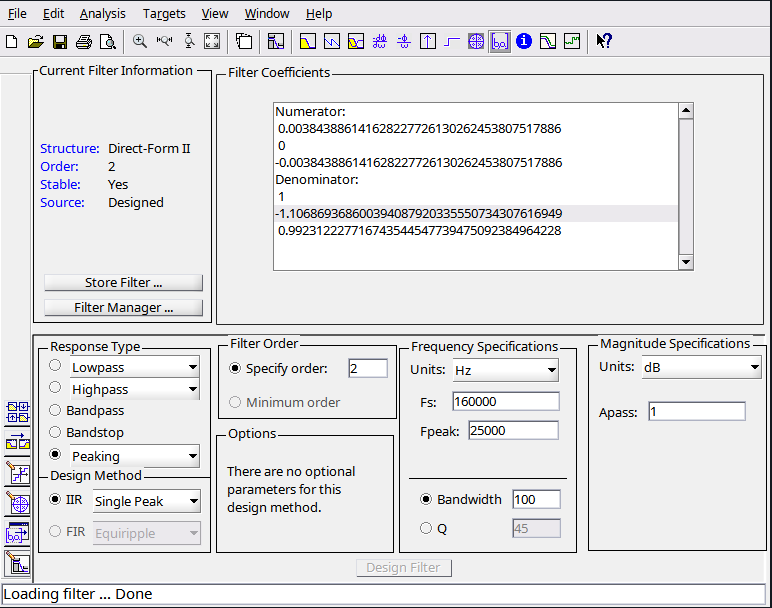ll

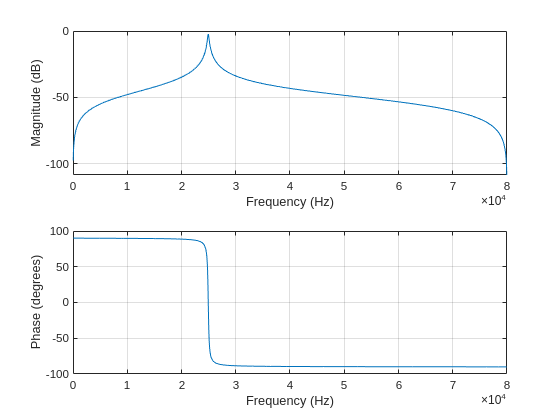

f_s = 160000;
b = [3.84E-3 0 -3.84E-3];
a = [1 -1.11 0.99];
freqz(b,a,2048,f_s);

Then, I derived my own to get an expression for H(z):

Peak at 25kHz => Put a pole at $0\ldotp 99\angle 2\pi \frac{f}{f_s }$ (and at the conjugate to cancel out the complex part).

Use 0.99 instead of 1 to dampen the response  - using 1 would give infinite gain at 25kHz.

Second-order => two zeroes

Put two zeroes at -1, 1, as shown in Slide 152

ps = [exp(-1i*2*pi*25/160) conj(exp(-1i*2*pi*25/160))]*0.99;
zs = [1 -1];
ps, zs

ps =    0.5500 - 0.8232i   0.5500 + 0.8232i


zs =      1    -1


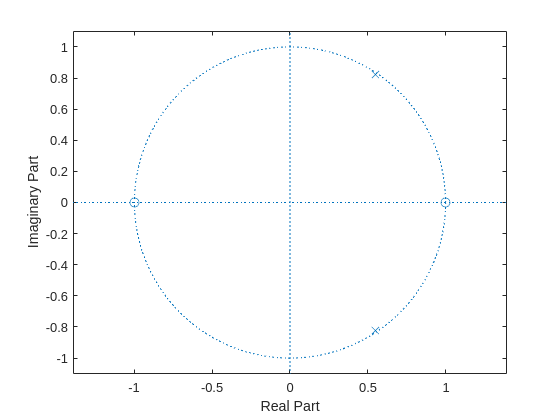

zplane(zs', ps')


$$\begin{array}{l}
H\left(z\right)=\frac{b_0 }{a_0 }\cdot z^{2-2} \cdot \frac{\left(z-c_1 \right)\left(z-c_2 \right)}{\left(z-d_1 \right)\left(z-d_2 \right)}\\
=k\cdot 1\cdot \frac{\left(z-1\right)\left(z+1\right)}{\left(z-\left(0\ldotp 55-0\ldotp 8232i\right)\right)\left(z-\left(0\ldotp 55+0\ldotp 8232i\right)\right)}\\
=k\cdot \frac{z^2 -1}{z^2 -1\ldotp 1z+0\ldotp {99}^2 }
\end{array}$$


The gain k was chosen by the Filter Designer to be 0.00384, presumably to take the peak down to 0dB.

The peak for the manual calculation was 40dB, so we take k=0.01 to bring that to 0dB.

k = 0.01;
b = [1 0 -1] * k;
a = [1 -1.1 0.99^2];
b, a

b =     0.0100         0   -0.0100


a =     1.0000   -1.1000    0.9801


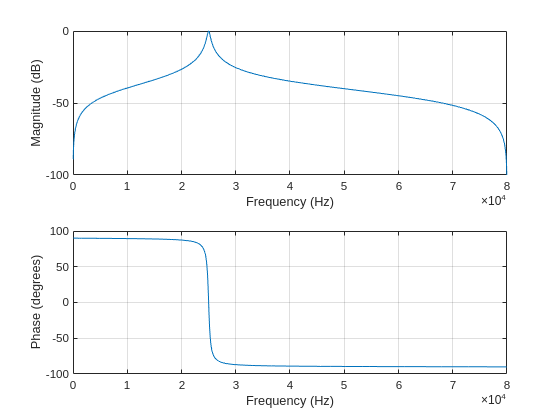

freqz(b,a,2048,f_s);

## Question 5


$$\begin{array}{l}
Y\left(z\right)=U\left(z\right)+b*X\left(z\right)*z^{-2} \\
U\left(z\right)=X\left(z\right)+c*U\left(z\right)*z^{-1} +a*X\left(z\right)*z^{-1} \\
\Rightarrow U\left(z\right)\left(1-c*z^{-1} \right)=X\left(z\right)\left(1+a*z^{-1} \right)\\
\Rightarrow U\left(z\right)=X\left(z\right)*\frac{1+{\mathrm{az}}^{-1} }{1-{\mathrm{cz}}^{-1} }\\
\Rightarrow Y\left(z\right)=X\left(z\right)*\frac{1+{\mathrm{az}}^{-1} }{1-{\mathrm{cz}}^{-1} }+X\left(z\right)*{\mathrm{bz}}^{-2} \\
\Rightarrow Y\left(z\right)=X\left(z\right)*\left(\frac{1+{\mathrm{az}}^{-1} }{1-{\mathrm{cz}}^{-1} }+{\mathrm{bz}}^{-2} \right)\\
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1+{\mathrm{az}}^{-1} }{1-{\mathrm{cz}}^{-1} }+{\mathrm{bz}}^{-2} 
\end{array}$$


## Question 6


$$\begin{array}{l}
y_n +y_{n-1} =x_n -x_{n-4} \\
\Rightarrow Y\left(z\right)\left(1+z^{-1} \right)=X\left(z\right)\left(1-z^{-4} \right)\\
\Rightarrow H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\left(1-z^{-4} \right)}{\left(1+z^{-1} \right)}=\frac{\left(1+z^{-2} \right)\left(1-z^{-2} \right)}{\left(1+z^{-1} \right)}=\frac{\left(1+z^{-2} \right)\left(1-z^{-1} \right)\left(1+z^{-1} \right)}{\left(1+z^{-1} \right)}\\
\Rightarrow H\left(z\right)=\left(1+z^{-2} \right)\left(1-z^{-1} \right)=1+z^{-2} -z^{-1} -z^{-3} =z^0 -z^{-1} +z^{-2} -z^{-3} \\
h_0 =1,h_1 =-1,h_2 =1,h_3 =-1\\
y_n =x_n -x_{n-1} +x_{n-2} -x_{n-3} 
\end{array}$$


**a) What is the impulse response of h?**


$$h\left\lbrace \delta_n \right\rbrace =\left\lbrace 1,-1,1,-1,0,0\ldotp \ldotp \ldotp \right\rbrace$$


**b) What is the step response of h?**

for $n=3$ onwards, $u_n ,u_{n-1} ,u_{n-2} ,u_{n-3}$ all equal 1 => for $y_n =h\left\lbrace u_n \right\rbrace ,\;y_3$ onwards = 0

similar calculations for $n=0,1,2$. y is causal, so $y_n =0\;\forall \;n<0$


$$h\left\lbrace u_n \right\rbrace =\left\lbrace 1,0,1,0,0\ldotp \ldotp \ldotp \right\rbrace$$


**c) Express as H(z)**

See above for working: $H\left(z\right)=\frac{\left(1-z^{-4} \right)}{\left(1+z^{-1} \right)}=z^0 -z^{-1} +z^{-2} -z^{-3}$

**d) Can you eliminate a common factor from numerator and denominator?**

See above for working - eliminated common factor of $\left(1+z^{-1} \right)$

The final H(z) has no denominator => it is a Finite Impulse Response filter, not an Infinite Impulse Reponse filter.

**e) Write H as a fraction using the position of its poles and zeros and draw their location in relation to the complex circle**


$$\begin{array}{l}
H\left(z\right)=1-z^{-1} +z^{-2} -z^{-3} =\frac{z^3 -z^2 +z^1 -1}{z^3 }=\frac{z^0 }{z^3 }\cdot \frac{z^3 -z^2 +z^1 -1}{1}\\
\Rightarrow k=0,m=3
\end{array}$$


3 zeros at nonzero locations in z

0 poles at nonzero locations in z

3 poles at z=0

Cubic function solver: $z^3 -z^2 +z^1 -1$

zs = roots([1 -1 1 -1])

zs =    1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i



$$z=1,j,-j\Rightarrow H\left(z\right)=0$$



$$H\left(z\right)=\frac{b_0 }{a_0 }\cdot z^{-3} \cdot \frac{\prod_{l=1}^3 \left(z-c_l \right)}{1}=\frac{\left(z-1\right)\left(z-j\right)\left(z+j\right)}{z\cdot z\cdot z}$$


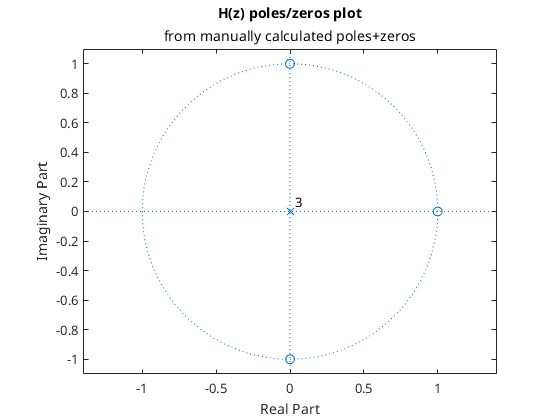

% Plot poles, zeroes on unit circle
figure;
zplane([1 1i -1i]', [0 0 0]');
title("H(z) poles/zeros plot");
subtitle("from manually calculated poles+zeros");

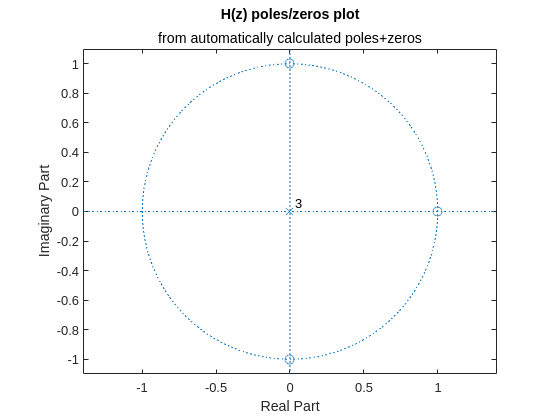

% For double checking - make zplane calculate the poles, zeros from the
% transfer function.
% Should match the previous one
zplane([1 -1 1 -1], [1 0 0 0]);
title("H(z) poles/zeros plot");
subtitle("from automatically calculated poles+zeros");

**f) If h is applied to file with sampling frequency 8000Hz, what frequency will be eliminated and what frequency will be quadrupled in amplitude?**


$$\begin{array}{l}
A\left(f\right)=|H\left(e^{\textrm{j2}\pi \frac{f}{f_s }} \right)|\\
f_s =8000\\
H\left(z\right)=\left(1+z^{-2} \right)\left(1-z^{-1} \right)\\
\Rightarrow |H\left(z\right)|=0\;\textrm{when}\;z^{-1} =1\;\textrm{or}\;z^{-2} =-1\\
\Rightarrow z=1\;\textrm{or}\;z=\pm j\\
\Rightarrow e^{\textrm{j2}\pi \frac{f}{f_s }} =1\;\textrm{or}\pm j\\
\Rightarrow f=0\;\textrm{or}\pm \textrm{j2}\pi \frac{f}{f_s }=j\frac{\pi }{2}\\
\textrm{Ignoring}\;\textrm{trivial}\;f=0\;\;\textrm{case}\ldotp \ldotp \ldotp \\
\pm 2\frac{f}{f_s }=\frac{1}{2}\Rightarrow f=\pm \frac{f_s }{4}=\pm \frac{8000}{4}=\pm 2000
\end{array}$$


For quadrupled amplitude...


$$\begin{array}{l}
|H\left(z\right)|=4=|1-z^{-1} +z^{-2} -z^{-3} |\\
\Rightarrow z^{-1} =-1\Rightarrow z=-1\\
\Rightarrow e^{\textrm{j2}\pi \frac{f}{f_s }} =-1\\
\Rightarrow \textrm{j2}\pi \frac{f}{f_s }=j\pi \\
\Rightarrow 2\frac{f}{f_s }=1\\
\Rightarrow \frac{f}{f_s }=\frac{1}{2}\\
\Rightarrow f=\frac{f_s }{2}=\frac{8000}{2}=4000
\end{array}$$


Sine waves of 2000Hz will be eliminated, sine waves of 4000Hz will be quadrupled in amplitude

Proof:

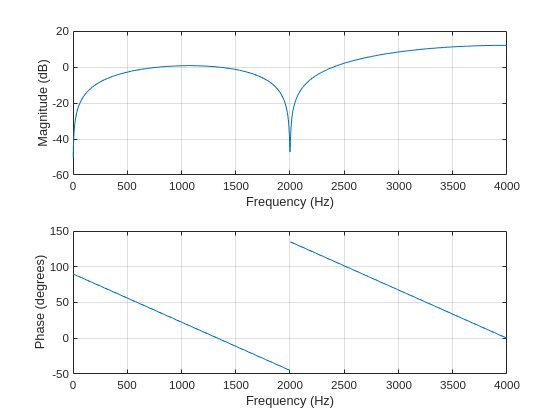

% From original definition
a = [1 1];%[1];
b = [1 0 0 0 -1];%[1 -1 1 -1];

f_s = 8000;
t = 1;
ts = 1/f_s:1/f_s:1;
x_2000 = sin(2*pi*2000*ts);
% Add phase offset to x_4000 so samples aren't all close to zero
x_4000 = sin(2*pi*4000*ts + 0.5);
freqz(b,a,2048,f_s);

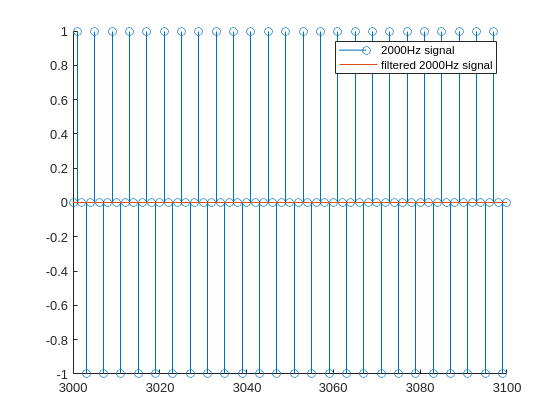


figure;
hold on;
stem(x_2000);
plot(filter(b,a,x_2000));
xlim([3000 3100]);
legend("2000Hz signal", "filtered 2000Hz signal");
hold off;

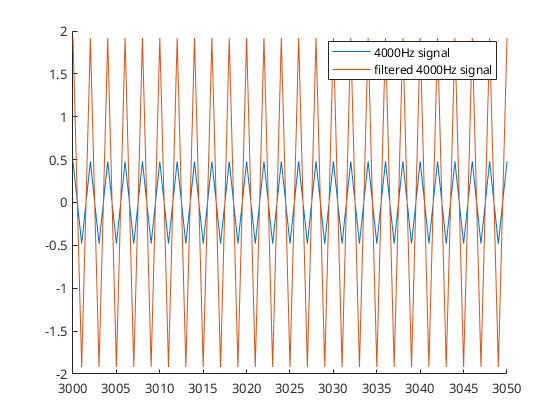


figure;
hold on;
plot(x_4000);
plot(filter(b,a,x_4000));
xlim([3000 3050]);
legend("4000Hz signal", "filtered 4000Hz signal");
hold off;